# Week 05 : Scientic Computing for Differential Equations

## Implicit Euler Method with Exact Newton Method

mu = 10;
x0 = [2.0 ; 0.0];
t0 = 0;
tf = (5*mu);
h0 = 0.0125;

abstol = 1e-7;
reltol = 1e-7;

[T,X1,info] = ImplicitEulerAdaptiveStep(@VanDerPol,t0,tf,x0,h0,abstol,reltol,mu);

info = struct with fields:
       nfun: 187811
    naccept: 93905
    nreject: 3
      nstep: 187814


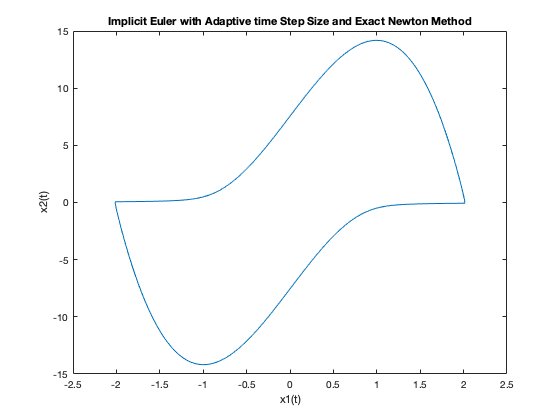

plot(X1(:,1),X1(:,2))
xlabel("x1(t)")
ylabel("x2(t)")
title("Implicit Euler with Adaptive time Step Size and Exact Newton Method")

## Implicit Euler Method with Inexact Newton Method

mu = 10;
x0 = [2.0 ; 0.0];
t0 = 0;
tf = (5*mu);
h0 = 0.0125;

abstol = 1e-7;
reltol = 1e-7;

[T,X2,info] = ImplicitEulerAdaptiveStep2(@VanDerPol,t0,tf,x0,h0,abstol,reltol,mu);

info = struct with fields:
       nfun: 187811
    naccept: 93905
    nreject: 3
      nstep: 187814


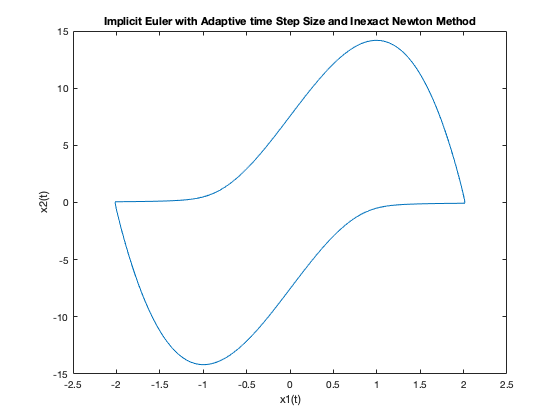

plot(X2(:,1),X2(:,2))
xlabel("x1(t)")
ylabel("x2(t)")
title("Implicit Euler with Adaptive time Step Size and Inexact Newton Method")

## With a solver

mu = 10;
x0 = [2.0; 0.0];
options = odeset('RelTol',1.0e-7,'AbsTol',1.0e-7);
[T,X3]=ode45(@VanDerPol,[0 5*mu],x0,options,mu);

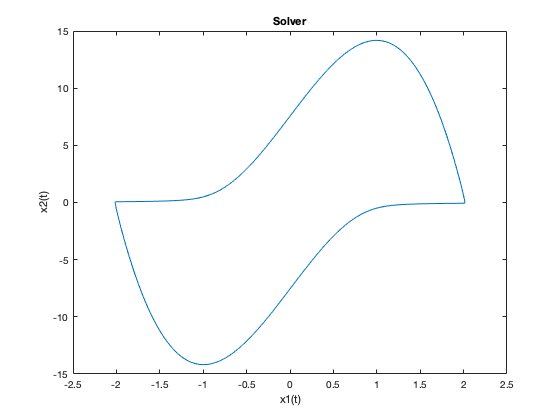

plot(X3(:,1),X3(:,2))
xlabel("x1(t)")
ylabel("x2(t)")
title("Solver")

## Comparison

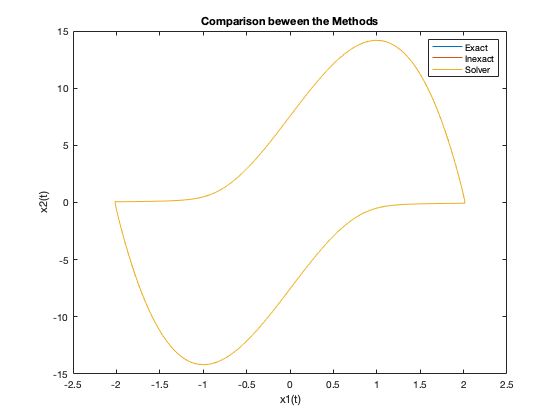

plot(X1(:,1),X1(:,2))
hold on
plot(X2(:,1),X2(:,2))
hold on 
plot(X3(:,1),X3(:,2))
hold off
xlabel("x1(t)")
ylabel("x2(t)")
title("Comparison beween the Methods")
legend('Exact','Inexact','Solver')